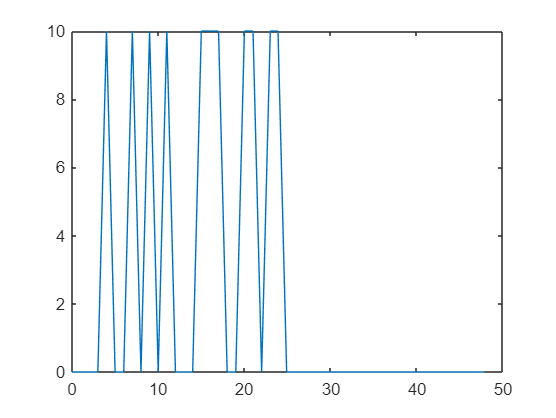

T = 24;              %segundos
Ts = 0.1;            %segundos/muestra
t = 0:Ts:T-Ts;       %vector tiempo de muestreo

f((t>0)&t<=3)=0;
f((t>3)&(t<=4))=1;
f((t>4)&(t<=6))=0;
f((t>6)&(t<=7))=1;
f((t>7)&(t<=8))=0;
f((t>8)&(t<=9))=1;
f((t>9)&(t<=10))=0;
f((t>10)&(t<=11))=1;
f((t>11)&(t<=14))=0;
f((t>14)&(t<=17))=1;
f((t>17)&(t<=19))=0;
f((t>19)&(t<=21))=1;
f((t>21)&(t<=22))=0;
f((t>22)&(t<=24))=1;

t2 = 0:0.1:50;

u = @(t) (t>=0);
x = @(t,d) u(t)-u(t-d);


%Señal impulso unitario
h = x(t,1);
y=conv(f,h,"full");
time = t(1)+t(1):0.1:t(length(t))+t(length(t));
plot(time,y);

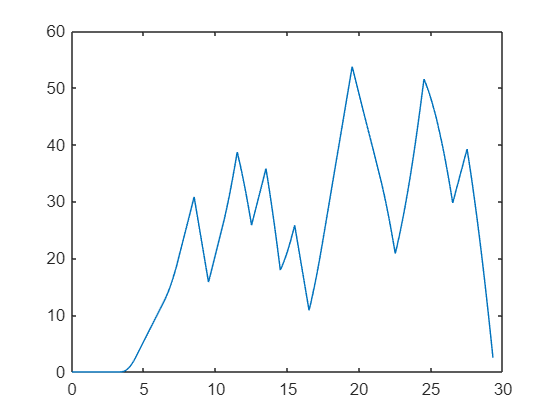


%Convolucion con la funcion de simulink
ht = out.tout;
t1 = 0:0.1:5.4;
y2 = conv(f,ht,'full');
time2 = t2(1)+t(1):0.1:t2(length(t2))+t(length(t));
plot(0:0.1:29.3,y2)

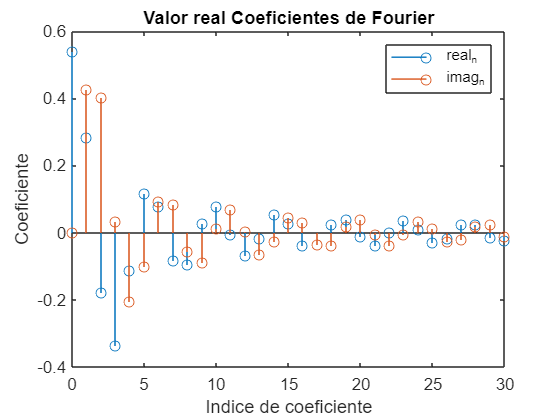

%h(t) desde simulink
%Calculo de coeficientes de Fourier
N = 30; 
realc = zeros(1,N+1);
imagc = zeros(1,N+1);

for n=0:N
    cosTerm = cos(2*pi*t1*n/T);
    sinTerm = sin(2*pi*t1*n/T);
    
    realc(n+1) = (2*Ts/T)*sum(transpose(ht).*cosTerm);
    imagc(n+1) = (2*Ts/T)*sum(transpose(ht).*sinTerm);
end

%Visualizar coeficientes 

stem(0:N, realc)
hold on
stem(0:N, imagc)
hold off
xlabel('Indice de coeficiente')
ylabel('Coeficiente')
legend('real_n','imag_n')
title('Valor Coeficientes de Fourier h(t) de simulink')

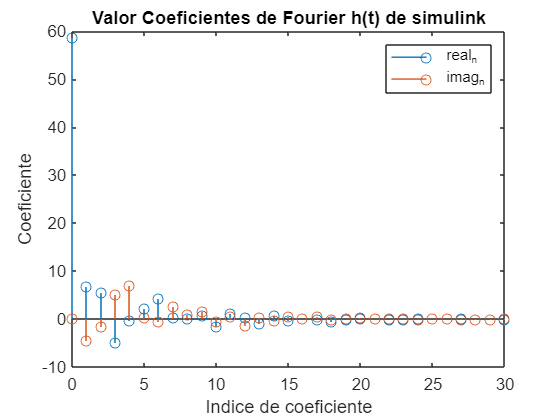

%%Coeficientes de Fourier convolución
%Borrar despues
th = 0:0.1:29.3;

%Calculo de coeficientes de Fourier
N = 30; 
realc = zeros(1,N+1);
imagc = zeros(1,N+1);

for n=0:N
    cosTerm = cos(2*pi*th*n/T);
    sinTerm = sin(2*pi*th*n/T);
    
    realc(n+1) = (2*Ts/T)*sum(y2.*cosTerm);
    imagc(n+1) = (2*Ts/T)*sum(y2.*sinTerm);
end

%Visualizar coeficientes 

stem(0:N, realc)
hold on
stem(0:N, imagc)
hold off
xlabel('Indice de coeficiente')
ylabel('Coeficiente')
legend('real_n','imag_n')
title('Valor Coeficientes de Fourier y(t) convolución')